% Par set 1

Lambda = 0.0004;
mu = Lambda;
b = Lambda;
beta = 2.5;
gamma = 1;
epsilon = 1;
alpha_i = 0;
alpha_s = 0.0008;


% Par set 2
%{
Lambda = 0.0004;
mu = Lambda;
b = Lambda;
beta = 1.5;
gamma = 1;
epsilon = 0.5;
alpha_i = 0;
alpha_s = 0.0001;
%}


chadi_par_keys = ["Lambda" "mu" "beta" "gamma" "epsilon" "alpha_i" "alpha_s"];
shrader_par_keys = ["b" "beta" "gamma" "epsilon" "alpha_i" "alpha_s"];

chadi_par_values = [Lambda mu beta gamma epsilon alpha_i alpha_s];
shrader_par_values = [b beta gamma epsilon alpha_i alpha_s];

chadi_par_dictionary = dictionary(chadi_par_keys, chadi_par_values);
shrader_par_dictionary = dictionary(shrader_par_keys, shrader_par_values);

tspan = [0 10000];
i0 = 1e-2;
x0_chadi = [1 - i0; i0; 0];
x0_shrader = [1 - i0; i0];

chadi_odefun = @(t,x) chadi_model(t, x, chadi_par_dictionary);
shrader_odefun = @(t,x) shrader_model(t, x, shrader_par_dictionary);
chadi_sol = ode89(chadi_odefun, tspan, x0_chadi)

chadi_sol = struct with fields:
     solver: 'ode89'
    extdata: [1×1 struct]
          x: [0 0.0371 0.2228 1.1511 2.6360 4.6091 5.7641 6.9191 8.3145 9.6065 11.1896 12.9286 15.0905 17.7119 21.1007 24.8619 27.2875 29.7131 33.2957 36.3612 39.4266 42.8547 46.1466 48.9932 51.7277 54.8620 58.4073 61.7261 64.5163 … ] (1×562 double)
          y: [3×562 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


shrader_sol = ode89(shrader_odefun, tspan, x0_shrader)

shrader_sol = struct with fields:
     solver: 'ode89'
    extdata: [1×1 struct]
          x: [0 0.2518 1.5109 3.1190 4.2769 5.4348 6.6799 7.9894 9.3191 10.7811 12.5039 14.5243 17.0288 20.2097 23.9439 26.4236 28.9033 32.4956 35.4637 38.4318 41.8613 45.1795 47.9483 50.5219 53.5250 57.0576 60.3930 63.0801 65.5930 … ] (1×3313 double)
          y: [2×3313 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


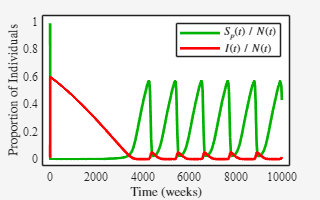

chadi_fig = figure("Position", [0 0 320 200]);
axis = axes(chadi_fig);
hold on;
N_time_series = sum(chadi_sol.y, 1);
plot(chadi_sol.x, chadi_sol.y(1,:) ./ N_time_series, "DisplayName", "$S_p(t)\; /\; N(t)$", "Color", [0 0.7 0], "LineWidth", 2);
plot(chadi_sol.x, chadi_sol.y(2,:) ./ N_time_series, "DisplayName", "$I(t)\; /\; N(t)$", "Color", [1 0 0], "LineWidth", 2);
xlabel("Time (weeks)", "Interpreter", "latex");
ylabel("Proportion of Individuals", "Interpreter", "latex")
legend("Interpreter", "latex");
box(axis, "on");
axis.XAxis.TickLength = [0 0];
axis.XAxis.FontName = "Times New Roman";
axis.YAxis.TickLength = [0 0];
axis.YAxis.FontName = "Times New Roman";

% Add axis padding
xlen = chadi_sol.x(end);
x_pad = xlen*0.035;
xlim([-x_pad, xlen + x_pad]);
ylim([-0.05, 1.05]);

theme(chadi_fig, "light");
hold off;

exportgraphics(chadi_fig, "MA_time_series_par_set_1.png", "Resolution", 300);

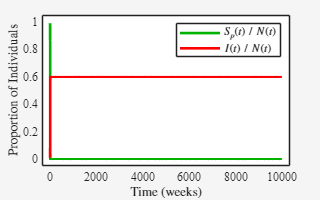


shrader_fig = figure("Position", [0 0 320 200]);
axis = axes(shrader_fig);
hold on;
plot(shrader_sol.x, shrader_sol.y(1,:), "DisplayName", "$S_p(t)\; /\; N(t)$", "Color", [0 0.7 0], "LineWidth", 2);
plot(shrader_sol.x, shrader_sol.y(2,:), "DisplayName", "$I(t)\; /\; N(t)$", "Color", [1 0 0], "LineWidth", 2);
xlabel("Time (weeks)", "Interpreter", "latex");
ylabel("Proportion of Individuals", "Interpreter", "latex")
legend("Interpreter", "latex");
box(axis, "on");
axis.XAxis.TickLength = [0 0];
axis.XAxis.FontName = "Times New Roman";
axis.YAxis.TickLength = [0 0];
axis.YAxis.FontName = "Times New Roman";

% Add axis padding
xlen = chadi_sol.x(end);
x_pad = xlen*0.035;
xlim([-x_pad, xlen + x_pad]);
ylim([-0.05, 1.05]);

theme(shrader_fig, "light");
hold off;

exportgraphics(shrader_fig, "ST_time_series_par_set_1.png", "Resolution", "300");

function dx_dt = chadi_model(t, x, par_dictionary)
    Lambda = par_dictionary("Lambda");
    mu = par_dictionary("mu");
    beta = par_dictionary("beta");
    gamma = par_dictionary("gamma");
    epsilon = par_dictionary("epsilon");
    alpha_i = par_dictionary("alpha_i");
    alpha_s = par_dictionary("alpha_s");

    Sp = x(1);
    I = x(2);
    Ss = x(3);

    dSp_dt = Lambda - beta*Sp*I - mu*Sp;
    dI_dt = beta*Sp*I + epsilon*beta*Ss*I - (gamma + mu + alpha_i)*I;
    dSs_dt = gamma*I - epsilon*beta*Ss*I - (mu + alpha_s)*Ss;

    dx_dt = [dSp_dt; dI_dt; dSs_dt];
end

function dx_dt = shrader_model(t, x, par_dictionary)
    b = par_dictionary("b");
    beta = par_dictionary("beta");
    gamma = par_dictionary("gamma");
    epsilon = par_dictionary("epsilon");
    alpha_i = par_dictionary("alpha_i");
    alpha_s = par_dictionary("alpha_s");

    sp = x(1);
    i = x(2);
    ss = 1 - sp - i;

    dsp_dt = b - b*sp - beta*sp*i + alpha_i*sp*i + alpha_s*sp*ss;
    di_dt = beta*sp*i + epsilon*beta*i*ss - (b + gamma + alpha_i)*i + alpha_i*i*i + alpha_s*i*ss;

    dx_dt = [dsp_dt; di_dt];
end